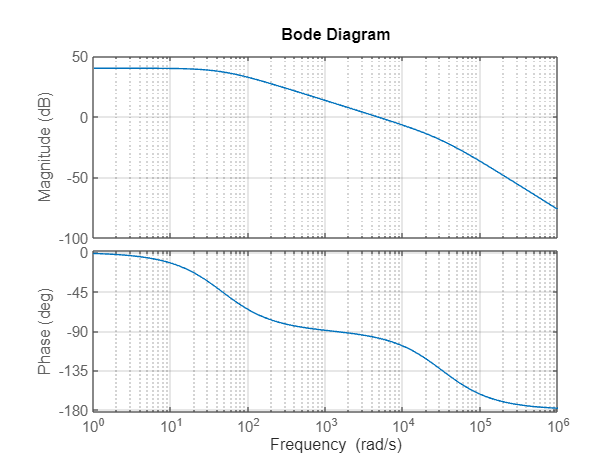

% Define the transfer function coefficients
sys = tf(1.477*10^8, [1, 3.205*10^4 1.477*10^6]);

% Plot the Bode plot
bode(sys);
grid on;

% Assuming sys is the transfer function of your system
Kp = dcgain(sys);  % Steady-state gain
steady_state_error = 1 / (1 + Kp);  % Steady-state error
fprintf('Steady-State Error: %.4f\n', steady_state_error*100);

Steady-State Error: 0.9901


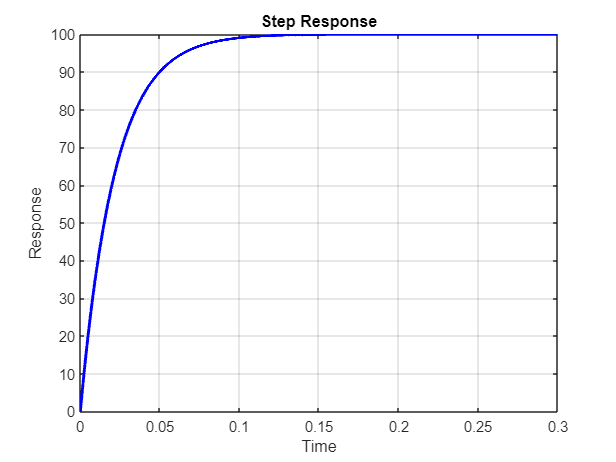

% Calculate the step response
t = 0:0.0001:0.3;                  % Time vector
[y, t] = step(sys, t);         % Calculate the step response

% Plot the step response
figure;
plot(t, y, 'b', 'LineWidth', 2);
xlabel('Time');
ylabel('Response');
title('Step Response');
grid on;

% Assuming y contains the step response of your system
tolerance_band = 0.02 * y(end);  % 2% settling criterion
settling_time_index = find(abs(y - y(end)) < tolerance_band, 1, 'first');
settling_time = t(settling_time_index);  % Time at which settling occurs
fprintf('Settling Time: %.4f\n ms', settling_time*1000);

Settling Time: 84.8000
 ms

% Plot the root locus
rlocus(sys);
title('Root Locus Plot');
xlabel('Real Part');
ylabel('Imaginary Part');
grid on;
poles = pole(sys)

poles = 1.0e+04 *

   -3.2004
   -0.0046


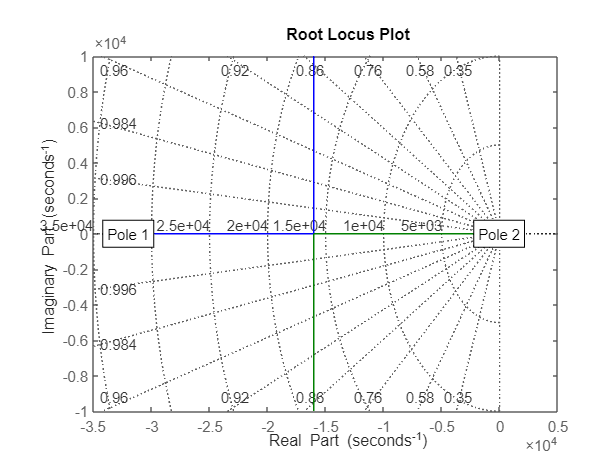

% Label the poles on the plot
for i = 1:length(poles)
    text(real(poles(i)), imag(poles(i)), ['Pole ' num2str(i)], ...
        'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', ...
        'BackgroundColor', 'white', 'EdgeColor', 'black');
end

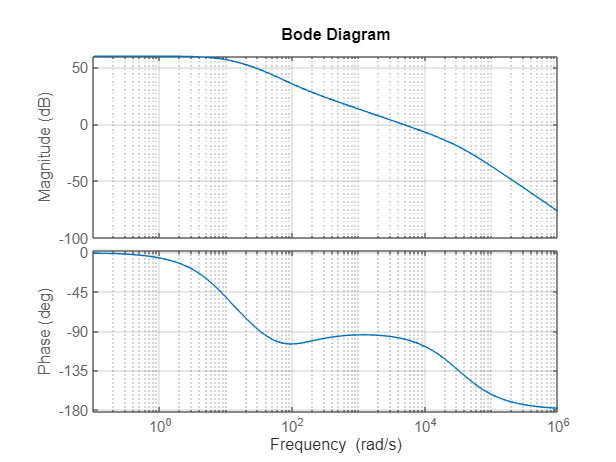

c = tf([200 200], [10,1]);

% close loop
 H = feedback(C*sys, 1);
bode(C*sys);
grid on;

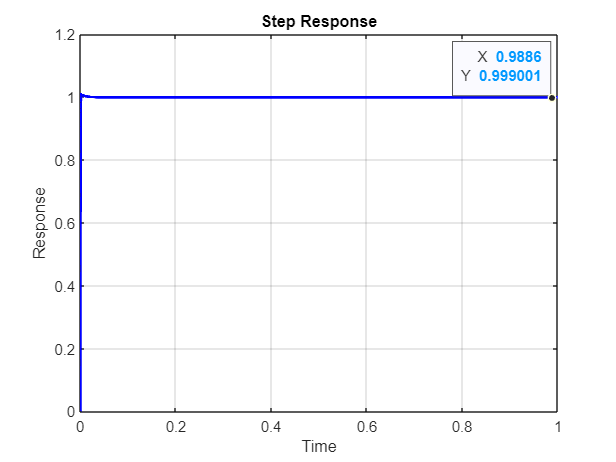

% Plot the step response of the closed-loop system
figure;
% Calculate the step response
t = 0:0.0001:1;                  % Time vector
[y, t] = step(H, t);         % Calculate the step response
% Plot the step response
figure;
plot(t, y, 'b', 'LineWidth', 2);
xlabel('Time');
ylabel('Response');
title('Step Response');
grid on;

% Label the last point
last_point = y(end);
text(length(y), last_point, ['(' num2str(length(y)) ', ' num2str(last_point) ')'], ...
    'HorizontalAlignment', 'left', 'VerticalAlignment', 'top');

ax = gca;
chart = ax.Children(2);
datatip(chart,0.9886,0.999);

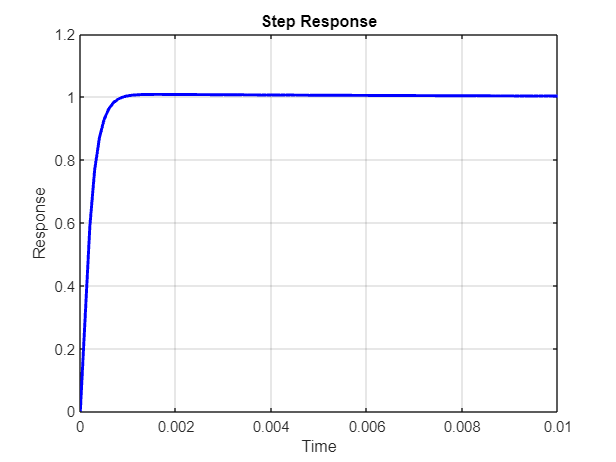

% Plot the step response of the closed-loop system
figure;
% Calculate the step response
t = 0:0.0001:0.01;                  % Time vector
[y, t] = step(H, t);         % Calculate the step response
% Plot the step response
figure;
plot(t, y, 'b', 'LineWidth', 2);
xlabel('Time');
ylabel('Response');
title('Step Response');
grid on;

% Label the last point
last_point = y(end);
text(length(y), last_point, ['(' num2str(length(y)) ', ' num2str(last_point) ')'], ...
    'HorizontalAlignment', 'left', 'VerticalAlignment', 'top');